# Defines pattern time for valves setting via bin functions.

### This example contains: 

- Add paths and load inp file. 

- Get times. 

- Create random settings. 

- Settings for valve 'VALVE-173'. 

- Check pressures at node after valve. 

- Run simulation with executable.

### Clear - Start Toolkit

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


###  Add paths and load inp file.

d=epanet('BWSN_Network_1.inp','Bin');

###  Get times.

t = d.getBinTimesInfo;
hydstep = t.BinTimeHydraulicStep;
duration = t.BinTimeSimulationDuration;

###  Create random settings.

a = 60; b = 90;
settings = (b-a).*rand((duration/hydstep)+1,1) + a;

###  Settings for valve 'VALVE-173'.

valveID = 'VALVE-173';
valveIndex = d.getBinLinkIndex(valveID);

###  Check pressures at node after valve.

nodeIndex = d.getBinNodeIndex('JUNCTION-112');
settings = num2str(settings,'%04.4f');

hrs = duration/3600;
hours = 0:hrs;
step = 0:hydstep/60:55; % step 30min
i=1; Time = cell(hrs,1);
for u=1:hrs
    for j=1:length(step)
        Time{i} = sprintf('%03d:%02d:00',hours(u),step(j));
        Controls(i,: ) = ['LINK ',valveID,' ',settings(i,:),' AT TIME ',Time{i}];
        i=i+1;
    end
end

d.addBinControl(Controls);

###  Run simulation with executable.

d.setCMDCODE(1)  % hide cmd messages..
Sim = d.getBinComputedAllParameters;
d.BinClose;

disp('Create random settings')

Create random settings


disp('----------------------')

----------------------


disp('a = 60; b = 90;')

a = 60; b = 90;


disp('settings = (b-a).*rand((duration/hydstep)+1,1) + a;')

settings = (b-a).*rand((duration/hydstep)+1,1) + a;


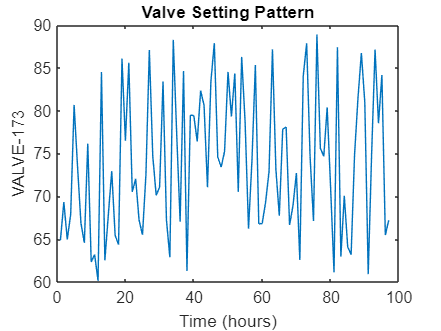


figure;
plot(Sim.BinNodePressure(:,nodeIndex));
title('Valve Setting Pattern');
xlabel('Time (hours)');
ylabel(valveID);